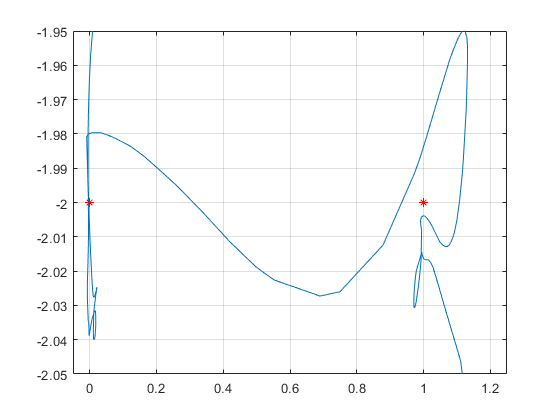

close all; clc; clear;
% a = out.acceleration.Data
% b = normalize(out.pwm.data,"range")
% [len,~] = size(a);
% for i=1:len
%     if a(i) < -10
%         a(i) = 0;
%     end
% end
% hold on
% a = a
% plot(a)
% plot(b)s
% save('variable_a6.txt', 'a', '-ASCII');
% save('variable_b6.txt', 'b', '-ASCII');

a = load("7.2_hover_and_move_3.txt"); %out.Pose.Data
%a = a(1:475,:);
a(:,3) = a(:,3)+0.55;

%save('7.2_hover_and_move_3.txt', 'a', '-ASCII');
figure(1)
plot(a(:,1), a(:,2))
hold on
plot(0, -2, "r*")
plot(1, -2, "r*")
xlim([-0.05 1.25])
ylim([-2.05 -1.95])
hold off
grid on 

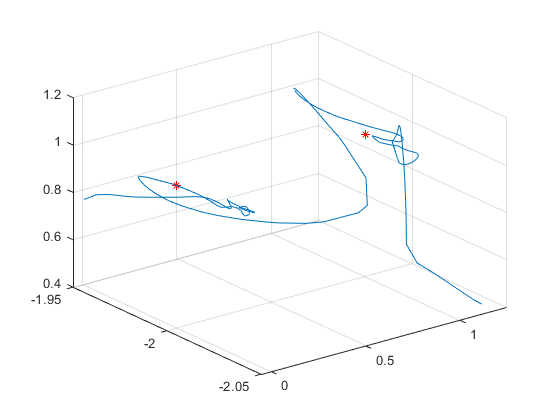


b = a-[0, -2, 1];

figure(2)
plot3(a(:,1), a(:,2), a(:,3), "LineStyle","-")
hold on
plot3(0, -2, 1, 'r*')
plot3(1, -2, 1, 'r*')
xlim([-0.05 1.25])
ylim([-2.05 -1.95])
hold off
grid on 

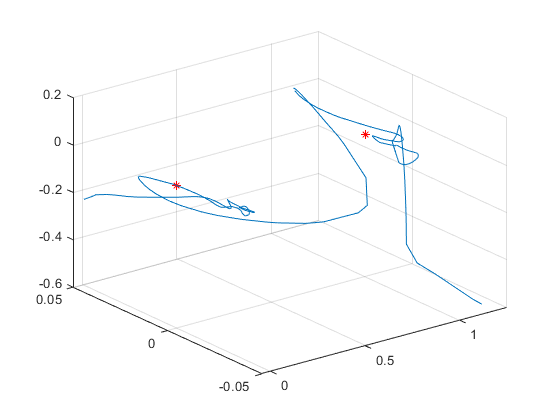



figure(3)
plot3(b(:,1), b(:,2), b(:,3), "LineStyle","-")
hold on
plot3(0, 0, 0, 'r*')
plot3(1, 0, 0, 'r*')
xlim([-0.05 1.25])
ylim([-0.05 0.05])
hold off
grid on 